# Event Distribution

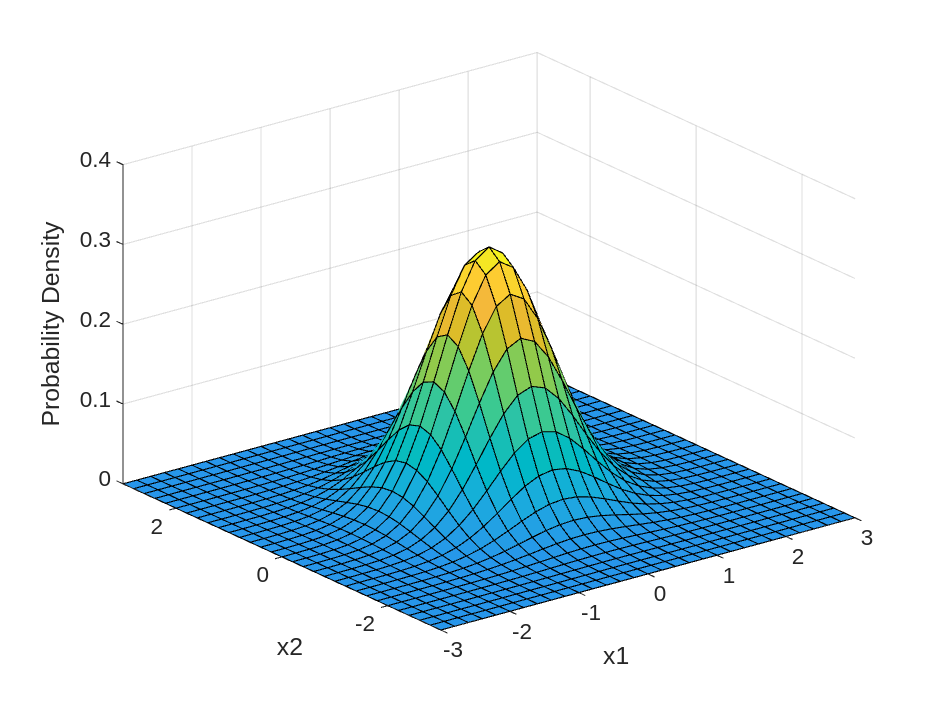

clear;clc;close;

mu = [0 0];
Sigma = [0.5 0.0;0.0 0.5];

x1 = -3:0.2:3;
x2 = -3:0.2:3;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];

y = mvnpdf(X,mu,Sigma);
y = reshape(y,length(x2),length(x1));

surf(x1,x2,y);
clim([min(y(:))-0.5*range(y(:)),max(y(:))]);
axis([-3 3 -3 3 0 0.4]);
xlabel('x1');
ylabel('x2');
zlabel('Probability Density');

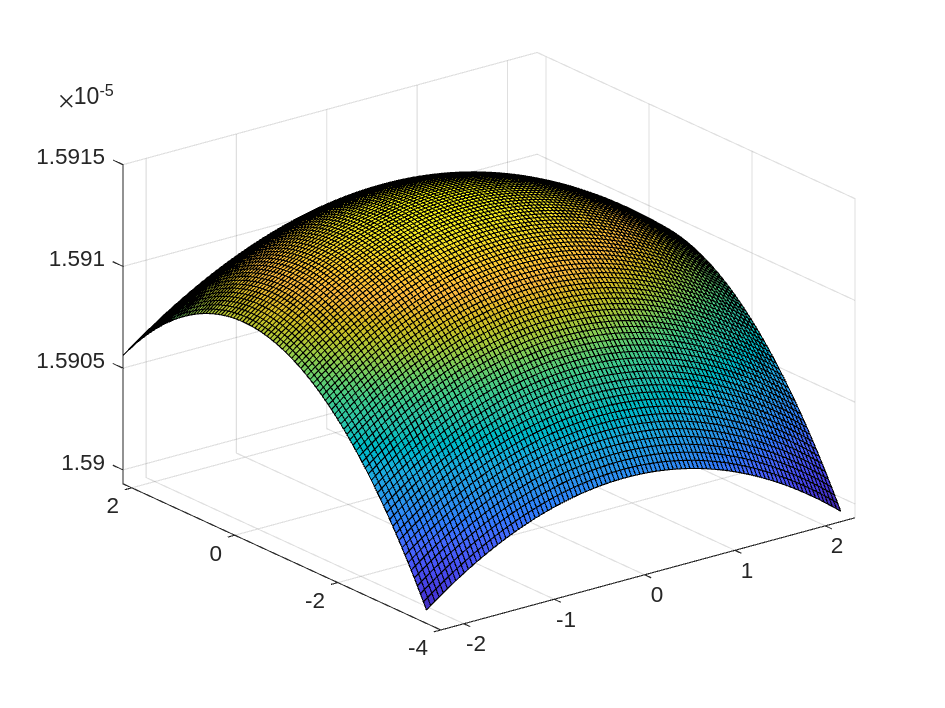

% generate some sample data
x = randn(100,1);
y = randn(100,1);

% create a grid of points to evaluate the density
xgrid = linspace(min(x), max(x), 100);
ygrid = linspace(min(y), max(y), 100);
[X,Y] = meshgrid(xgrid, ygrid);
xy = [X(:) Y(:)];

% estimate the density using a Gaussian kernel
k = 100;  % bandwidth parameter
f = ksdensity([x y], xy, 'Bandwidth', k);

% plot the density surface
surf(X, Y, reshape(f, size(X)));

# Detecting Probability of points in FoV

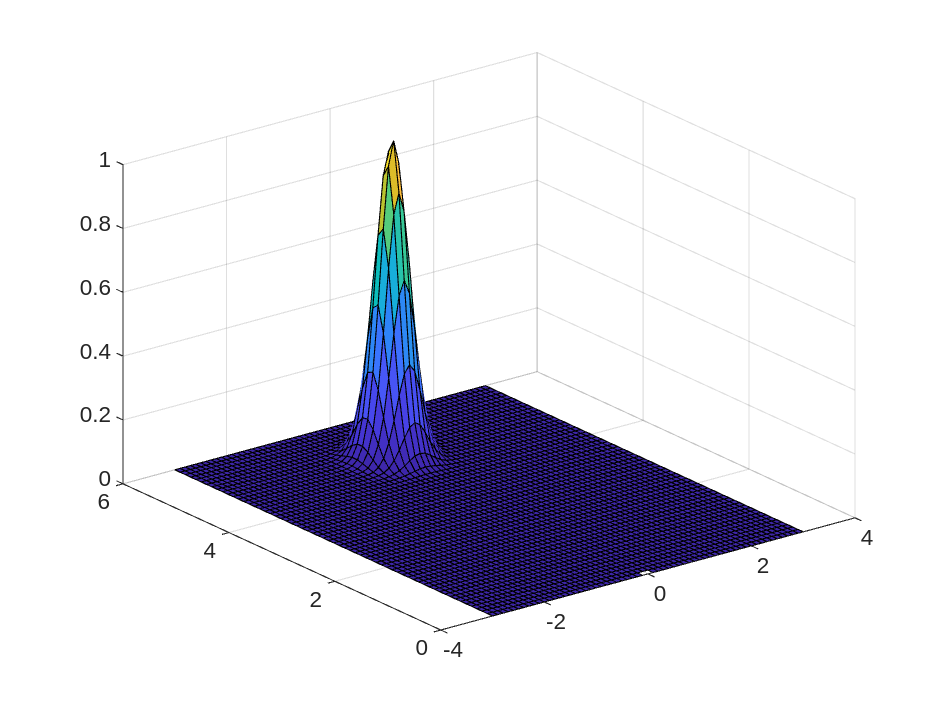

clear;clc;close;

pos = [0;0];
x1 = -3:0.1:3;
x2 = 0:0.1:6;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)]';

perspective = [0;1]; perspective = perspective/norm(perspective);
AOV = pi/6; alpha = AOV*0.5; range = 5;

d = vecnorm(X - pos); a =  acos( ((X - pos)./d)'*perspective );
y = exp( -( d - range*cos(alpha)).^2./(2*(range*cos(alpha)^2)*0.1^2) ).*exp( -(a.^2)./(2*alpha^2*0.2^2) )';
y = reshape(y,length(x2),length(x1));

surf(x1,x2,y);

# Probability of points on the boundary of FoV

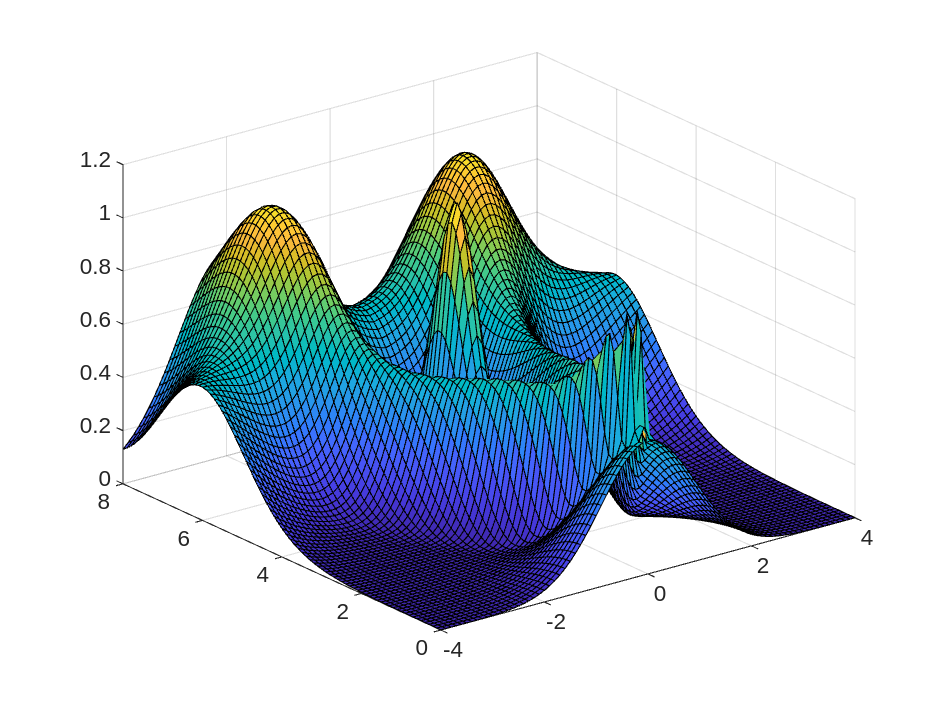

clear;clc;close;

pos = [0;0];
x1 = -4:0.1:4;
x2 = 0:0.1:8;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)]';

perspective = [0;1]; perspective = perspective/norm(perspective);
AOV = pi/6; alpha = AOV*0.5; range = 5; lambda = 2; range_max = ( (lambda+1)/lambda )*range*cos(alpha);

d = vecnorm(X - pos); a =  acos( ((X - pos)./d)'*perspective );

y1 = exp( -( d - range*cos(alpha)).^2./(2*(range*cos(alpha)^2)*0.2^2) ).*exp( -(a.^2)./(2*alpha^2*0.2^2) )';
y2 = exp( -( abs(d - 0.5*range_max) - 0.5*range_max ).^2./(2*(0.5*range_max)^2*0.25^2) ) + exp( -(abs(a) - alpha).^2./(2*alpha^2*0.35^2) )'...
   + exp( -( d - 0.5*range).^2./(2*(0.5*range^2)*0.3^2) ).*exp( -(a.^2)./(2*alpha^2*0.5^2) )';
y2 = (y2 - min(y2))./(max(y2)-min(y2));
y = y1 + y2;

Y1 = reshape(y1,length(x2),length(x1));
Y2 = reshape(y2,length(x2),length(x1));
Y = reshape(y,length(x2),length(x1));

% surf(x1, x2, Y1);
% surf(x1, x2, Y2);
surf(x1, x2, Y);

# Angle Penalty

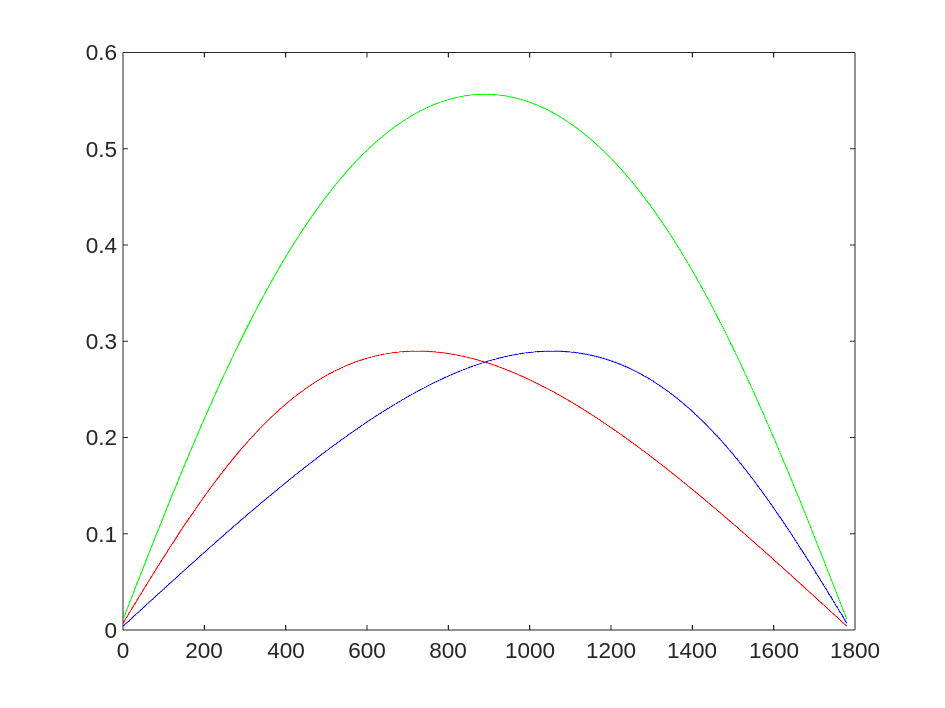

clear;clc;close

a = [-2;4]; b = [2;4]; mid = [0;4];
l = 7; c = zeros(2, 1781); count = 1;

for i = 181:0.1:359

    c(:, count) = [l*cosd(i); 4+l*sind(i)];
    count = count + 1;
end

perspective = mid - c; perspective = perspective./vecnorm(perspective, 2);
line_l = a - c; line_l = line_l./vecnorm(line_l, 2);
line_r = b - c; line_r = line_r./vecnorm(line_r, 2);
theta_l = acos(dot(perspective, line_l)); theta_r = acos(dot(perspective, line_r));
theta = theta_l + theta_r;

l_l = 2.*exp(0.7*(pi/6) - theta_l); l_r = 2.*exp(0.7*(pi/6) - theta_r);
l = l_l + l_r;

plot(0:1:1780, theta_l, "r", 0:1:1780, theta_r, "b", 0:1:1780, theta, "g");

## Cost Function Plot

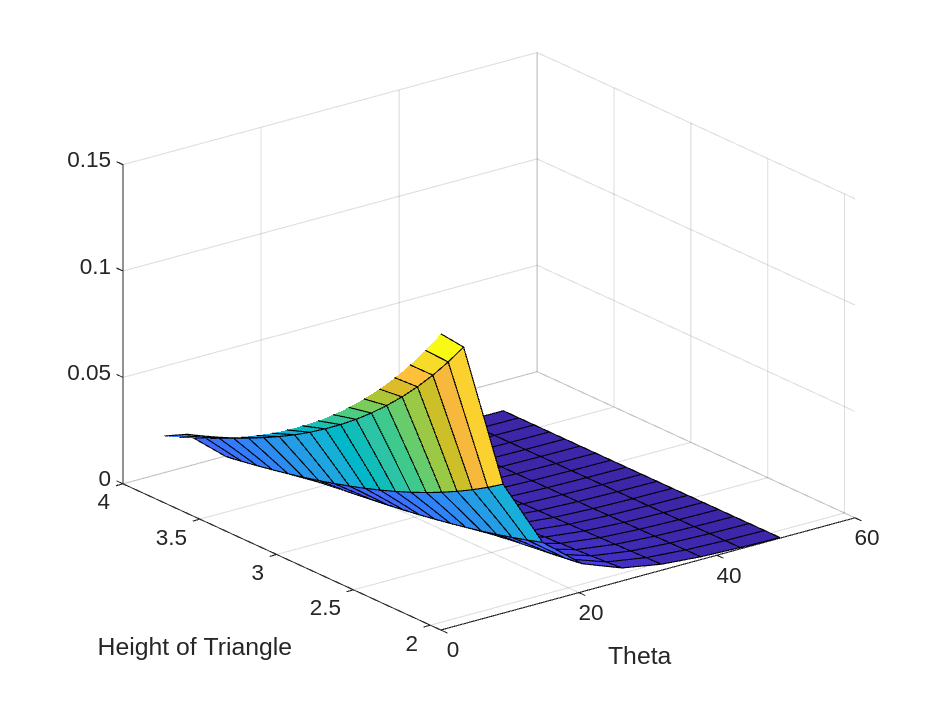

clear;clc;close;

AOV = pi/6; alpha = AOV*0.5; range = 5; lambda = 2; range_max = ( (lambda+1)/lambda )*range*cos(alpha);
hn = range_max - range*cos(alpha); l = 2;

pos = [0;0];
theta = -0.3*pi:0.1:0.3*pi;
h = 0.8*hn:0.1:0.6*pi+0.8*hn;
[X1,X2] = meshgrid(theta,h);
X = [X1(:) X2(:)]';

% C3 = exp( (1./((X(2,:)./hn).*exp(abs(X(1,:))-0.5*alpha)./(2*0.3^2)) - 0.5) );
C3 = exp( -((X(2,:)/hn).*(1/(2*0.5^2))) ).*exp( -((abs(X(1,:)))/(alpha)).*(1/(2*0.5^2)) );
Y3 = reshape(C3, length(theta), length(h));
surf(theta.*(180/pi), h, Y3);
xlabel("Theta"); ylabel("Height of Triangle")
xlim([0 60]);

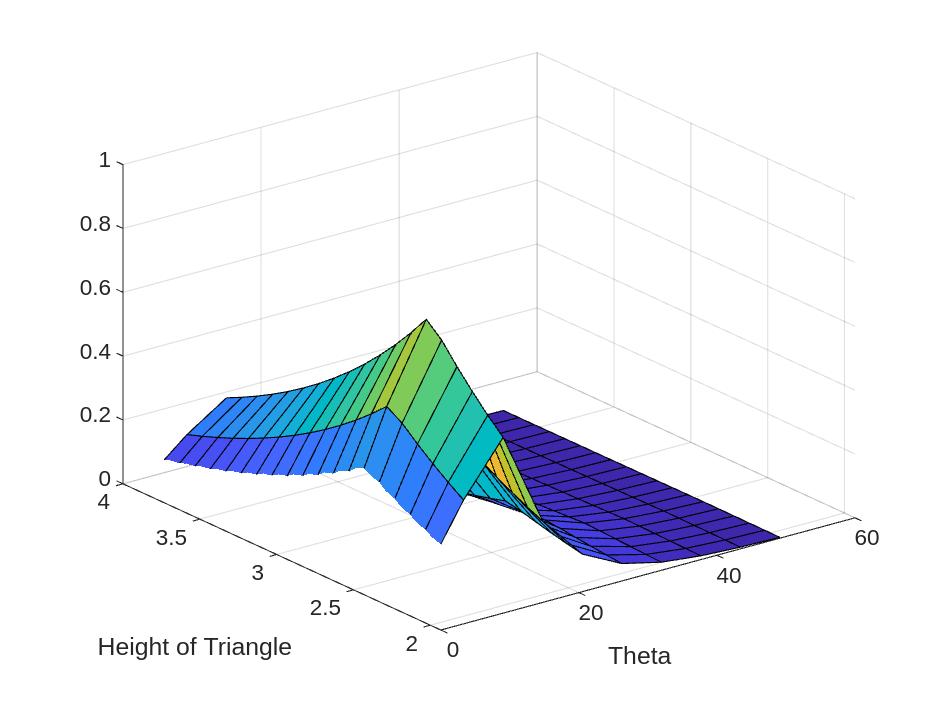

% C2 = exp( ( (X(2,:)./hn).*exp(abs(X(1,:))-alpha) - 0.5).*...
%         ( (0.5.*l.*exp(alpha-0.5.*abs(X(1,:)))+0.5.*l.*exp(alpha-0.5.*abs(X(1,:))))./l - 0.5) );
C2 = exp( -( (abs(abs(X(2,:)-1*hn))./hn).*(1/(2*0.5^2)) ) )...
    .*exp( -( (abs(abs(X(1,:)-0.5*alpha))./alpha).*(1/(2*0.5^2)) ) )...
    .*exp( -( ( (l - 0.5.*l.*exp(0.5*alpha-0.5.*abs(X(1,:))) - 0.5.*l.*exp(0.5*alpha-0.5.*abs(X(1,:))))./l ).*((1/2*0.5^2)) )  );
Y2 = reshape(C2, length(theta), length(h));
surf(theta.*(180/pi), h, Y2);
xlabel("Theta"); ylabel("Height of Triangle")
xlim([0 60]);

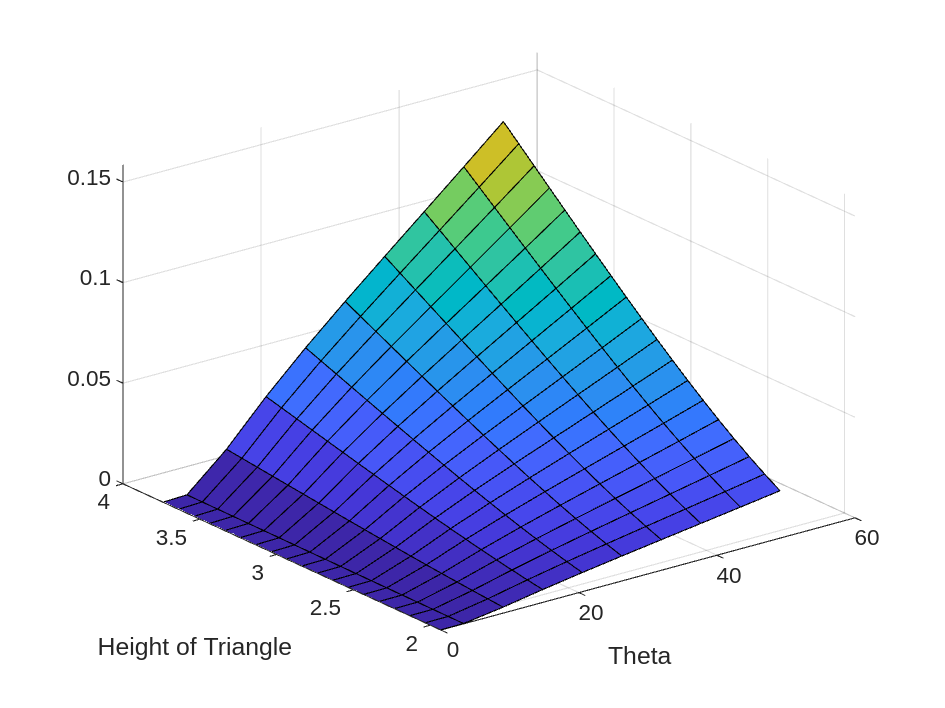

% C1 = exp( l./(0.5.*l.*exp(alpha-0.5.*abs(X(1,:)))+0.5.*l.*exp(alpha-0.5.*abs(X(1,:)))) - 0.5 );
C1 = exp( -( ( (1.5*hn./X(2,:)).*( 1/(2*0.5^2) ) ) ) )...
    .*exp( -( (0.5*alpha./abs(X(1,:))).*(1/(2*0.5^2)) ) )...
    .*exp( -( ( (0.5.*l.*exp(alpha-0.5.*abs(X(1,:))) + 0.5.*l.*exp(alpha-0.5.*abs(X(1,:))) - l)/l ).*(1/(2*0.5^2)) ) );
Y1 = reshape(C1, length(theta), length(h));
surf(theta.*(180/pi), h, Y1);
xlabel("Theta"); ylabel("Height of Triangle")
xlim([0 60]);

# Test

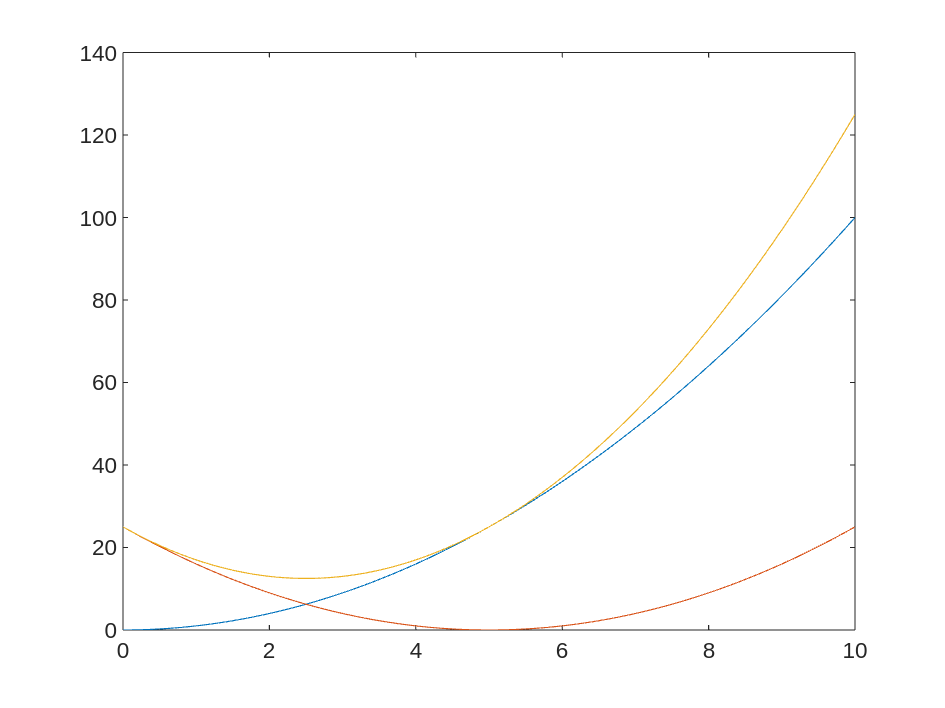

clear;clc;close;

x1 = 0:0.1:10; y1 = (x1).^2;
x2 = 0:0.1:10; y2 = (x2-5).^2;
plot(x1, y1, x2, y2, x1, y1+y2);

# Step Function Minic

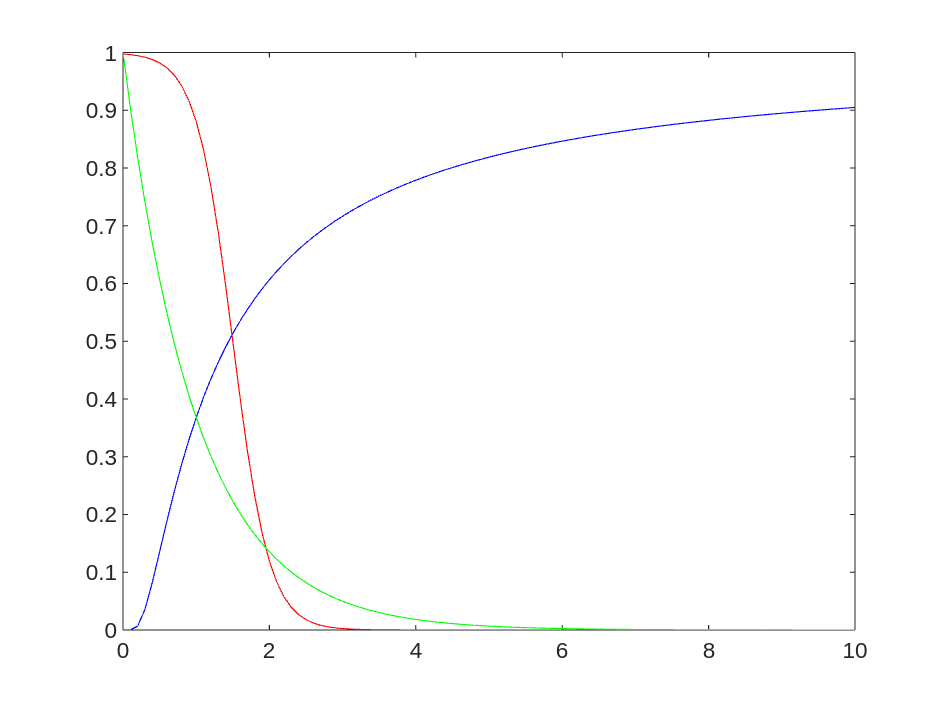

clear;clc;close

k = 2;
x = 0:0.1:10;
y = 1-(0.5 + 0.5*tanh(k.*(x-1.5)));

x1 = 0:0.1:10;
y1 = exp( -(0.5./x1).*(1/(2*0.5^2)) );

x2 = 0:0.1:10;
y2 = exp( -((x1)./2).*(1/(2*0.5^2)) );

plot(x, y, "r", x1, y1, "b", x2, y2, "g");

# Rotation Plant

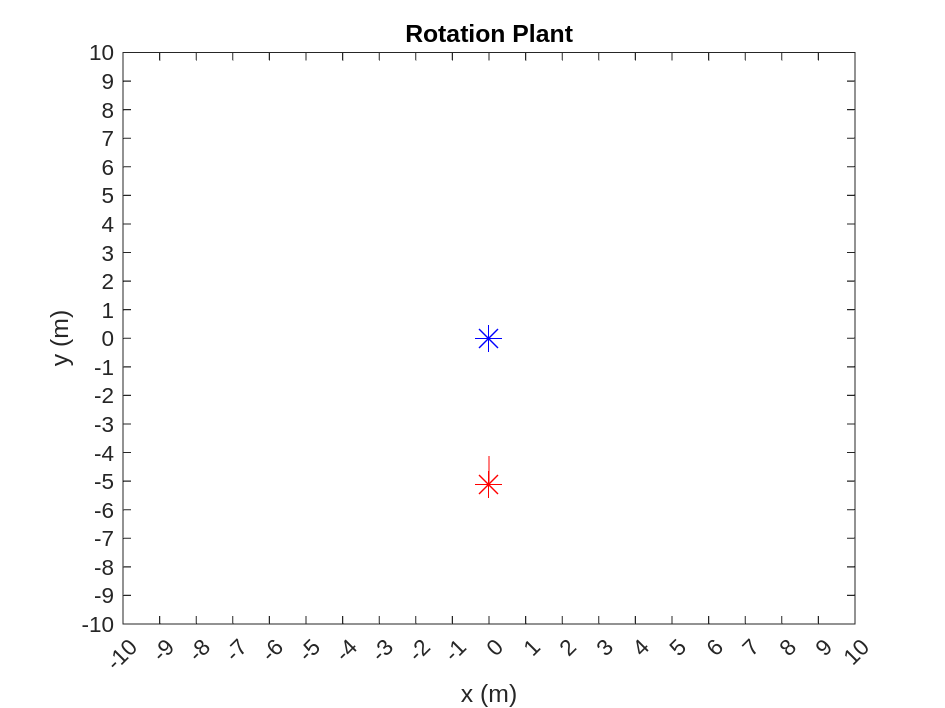

clear;clc;close;

center = [0;0]; p = [2;0]; r = 5.0;
v = center - p; v = v/norm(v);
dt = 0.5;

obstacle = [2;1]; safe_d = 3;

for i = 1:500

    center_force = center - p; center_force_norm = norm(center_force); center_force_normal = center_force/center_force_norm;
    replusive_force = p - center; replusive_force_norm = norm(replusive_force); replusive_force_normal = replusive_force/replusive_force_norm;

    R = [cos(-0.5*pi) -sin(-0.5*pi);sin(-0.5*pi) cos(-0.5*pi)];
    % drive_force = 2*R*replusive_force;
    if norm(p - obstacle) > 3

        drive_force = ([0;-5] - p)*2;
    else

        drive_force = norm(p - obstacle)*R*replusive_force;
    end

    drive_force_norm = norm(drive_force); drive_force_normal = drive_force/drive_force_norm;
    
    formation_force = ( center_force_normal*(drive_force_norm/(center_force_norm + drive_force_norm)) +... 
                        drive_force_normal*(center_force_norm/(center_force_norm + drive_force_norm)) );

    formation_force = formation_force + replusive_force_normal*(r - norm(p - center));
    formation_force_normal = formation_force/norm(formation_force);

    p = p + formation_force*dt;
    v = center - p; v = v/norm(v);
    head = p + 0.2*r.*v;

    % Conic Field View
    plot(p(1,1), p(2,1), "r*", 0, 0, "b*" , 'MarkerSize', 12);
    % plot(p(1,1), p(2,1), "r*", 'MarkerSize', 12);
    line([p(1,1), head(1,1)], [p(2,1), head(2,1)], 'Color', 'r');

    % Configuration of Figure
    title("Rotation Plant");
    xlabel("x (m)"); ylabel("y (m)");
    xlim([-10 10]); xticks(-10:1:10); 
    ylim([-10 10]); yticks(-10:1:10);
    drawnow;
    pause(1/1000);

    hold off;

    if i < 500

        clf;
    end
end

# Control Law

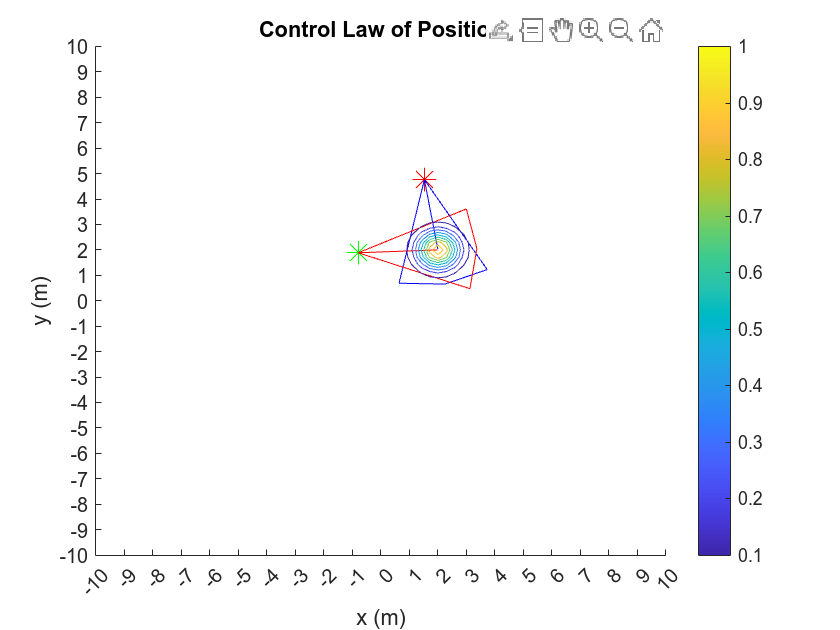

clear;clc;close;

p1 = [0;7]; v1 = [0;-1]; v1 = v1/norm(v1); H1_p = 0.0;
p2 = [-5;-2]; v2 = [+0.5;-0.5]; v2 = v2/norm(v2); H2_p = 0.0;
AOV = pi/6; alpha = AOV*0.5; range = 3; lambda = 2; range_max = ( (lambda+1)/lambda )*range*cos(alpha);
alpha1 = alpha;  alpha2 = alpha;

% Event Density Funciton
f = @(x) 1+exp( -(vecnorm(x-[2.0;2.0])).^2./(2*1.5^2) );
f_ = @(x, y) exp( -( (x-2.0).^2 + (y-2.0).^2 )./(2*0.5^2) );

for i = 1:200

    % Gradient Ascent
    [p1_dot, v1_dot, a1_dot, H1] = GA(p1, v1, alpha1, range, lambda);

    if ( (H1-H1_p)/H1 ) < 0.01
        p1 = p1 + 0.1.*[p1_dot(1,1);p1_dot(2,1)];
        v1 = v1 + 0.1.*[v1_dot(1,1);v1_dot(2,1)]; v1 = v1./norm(v1);
        alpha1 = alpha1 + 0.001*a1_dot;
    else
        p1_dot = p1_dot./norm(p1_dot);
        p1 = p1 + 0.1.*[p1_dot(1,1);p1_dot(2,1)];
        v1 = v1 + 0.1.*[v1_dot(1,1);v1_dot(2,1)]; v1 = v1./norm(v1);
        alpha1 = alpha1 + 0.001*a1_dot;
    end

    H1_p = H1;

    R = [cos(alpha1) -sin(alpha1);sin(alpha1) cos(alpha1)];
    range_max = ( (lambda+1)/lambda )*range*cos(alpha1);

    top1 = p1 + range_max*v1;
    ltop1 = p1 + range_max*( R*v1 );
    rtop1 = p1 + range_max*( (R')*v1);
    head1 = p1 + range*cos(alpha1).*v1;

    [p2_dot, v2_dot, a2_dot, H2] = GA(p2, v2, alpha2, range, lambda);

    if ( (H2-H2_p)/H2 ) < 0.01
        p2 = p2 + 0.1.*[p2_dot(1,1);p2_dot(2,1)];
        v2 = v2 + 0.1.*[v2_dot(1,1);v2_dot(2,1)]; v2 = v2./norm(v2);
        alpha2 = alpha2 + 0.001*a2_dot;
    else
        p2_dot = p2_dot./norm(p2_dot);
        p2 = p2 + 0.1.*[p2_dot(1,1);p2_dot(2,1)];
        v2 = v2 + 0.1.*[v2_dot(1,1);v2_dot(2,1)]; v2 = v2./norm(v2);
        alpha2 = alpha2 + 0.001*a2_dot;
    end

    H2_p = H2;

    R = [cos(alpha2) -sin(alpha2);sin(alpha2) cos(alpha2)];
    range_max = ( (lambda+1)/lambda )*range*cos(alpha2);

    top2 = p2 + range_max*v2;
    ltop2 = p2 + range_max*( R*v2 );
    rtop2 = p2 + range_max*( (R')*v2);
    head2 = p2 + range*cos(alpha2).*v2;

    hold on;

    % Conic Field View
    plot(p1(1,1), p1(2,1), "r*", p2(1,1), p2(2,1), "g*", 'MarkerSize', 12);

    line([p1(1,1), ltop1(1,1)], [p1(2,1), ltop1(2,1)], 'Color', 'b');
    line([ltop1(1,1), top1(1,1)], [ltop1(2,1), top1(2,1)], 'Color', 'b');
    line([top1(1,1), rtop1(1,1)], [top1(2,1), rtop1(2,1)], 'Color', 'b');
    line([rtop1(1,1), p1(1,1)], [rtop1(2,1), p1(2,1)], 'Color', 'b');
    line([p1(1,1), head1(1,1)], [p1(2,1), head1(2,1)], 'Color', 'b');

    line([p2(1,1), ltop2(1,1)], [p2(2,1), ltop2(2,1)], 'Color', 'r');
    line([ltop2(1,1), top2(1,1)], [ltop2(2,1), top2(2,1)], 'Color', 'r');
    line([top2(1,1), rtop2(1,1)], [top2(2,1), rtop2(2,1)], 'Color', 'r');
    line([rtop2(1,1), p2(1,1)], [rtop2(2,1), p2(2,1)], 'Color', 'r');
    line([p2(1,1), head2(1,1)], [p2(2,1), head2(2,1)], 'Color', 'r');

    % Density Function of Event
    fcontour(f_);
    colorbar;

    % Configuration of Figure
    title("Control Law of Position");
    xlabel("x (m)"); ylabel("y (m)");
    xlim([-10 10]); xticks(-10:1:10); 
    ylim([-10 10]); yticks(-10:1:10);
    drawnow;
    pause(1/1000);

    hold off;

    if i < 200

        clf;
    end
end

function [p_dot, v_dot, a_dot, H] = GA(p, v, alpha, range, lambda)

    % Configuration
    mu = [2 2];
    Sigma = [0.5 0.0;0.0 0.5];
    x1 = -15:0.1:15;
    x2 = -15:0.1:15;
    [X1,X2] = meshgrid(x1,x2);
    X = [X1(:) X2(:)];
    
    y = mvnpdf(X,mu,Sigma);
    % y = reshape(y,length(x2),length(x1));
    
    % F = f(X);
    F = y'; X = X';
    d = vecnorm(X - p); index = (d == 0); d(index) = 1;

    q_pers = @(X) ( (1)/(1-cos(alpha)) ).*( ((X-p)'*v)'./(d) - cos(alpha) );
    q_res = @(X) ( ( d.^lambda./(range^(lambda+1)) ).*( range.*cos(alpha) - lambda.*(d-range.*cos(alpha)) ) );

    Q_pers = q_pers(X); Q_res = q_res(X); Q = Q_pers.*Q_res;
    V_pers = q_pers(X) >= 0; V_res = q_res(X) >= 0; V_total = V_pers.*V_res;
    V_index = find(V_total);
    V = X(:, V_index); d = d(V_index); F = F(V_index);

    Q = Q(:,V_index);
    H = sum(Q.*F);

    p_dot = ( (lambda+1)/(1-cos(alpha)) ).*( (((V-p)'*v)'./(d.^3)).*(V-p) - v./d ).*( cos(alpha) - (lambda/(range*lambda+range)).*d ).*( (d.^lambda)./(range^lambda) )...
    + ( (lambda+1)/(1-cos(alpha)) ).*( ((V-p)'*v)'./(d) - cos(alpha) ).*( (cos(alpha)/(range^lambda)).*(-lambda).*(d.^(lambda-2)).*(V-p) + lambda/(range^(lambda+1)).*(d.^(lambda-1)).*(V-p) );
    p_dot = sum(p_dot.*F*0.1, 2);

    v_V = ( (lambda+1)/(1-cos(alpha)) ).*( (V-p)./d ).*( cos(alpha) - (lambda/(range*lambda+range)).*d ).*( (d.^lambda)./(range^lambda) );
    v_V = sum(v_V.*F*0.1, 2); 
    v_dot = v_V./norm(v_V);

    a_dot = ( lambda+1 ).*( -sin(alpha) ).*( (d.^lambda)./(range^lambda) )...
    + ( lambda+1 ).*( sin(alpha)/((1-cos(alpha))^2) ).*( 1 - ((V-p)'*v)'./(d) ).*( 1 - (lambda/(range*lambda+range)).*d ).*( (d.^lambda)./(range^lambda) );
    a_dot = sum(a_dot.*F*0.1);
end